load("Tyto_sample_2207_2300kv_5030x3_4S.mat")

cmd = (Throttles(2:end)-1147)/1000;
thrust = Thrustkgf(2:end)*9.807;
omega = RotationSpeedrpm(2:end)*(2*pi/60);
drag = TorqueNm(2:end);

cmd2omegaSq = fit(cmd, omega.^2, 'poly1');
cmd2omegaSq_k = cmd2omegaSq.p1

cmd2omegaSq_k = 8.7240e+06

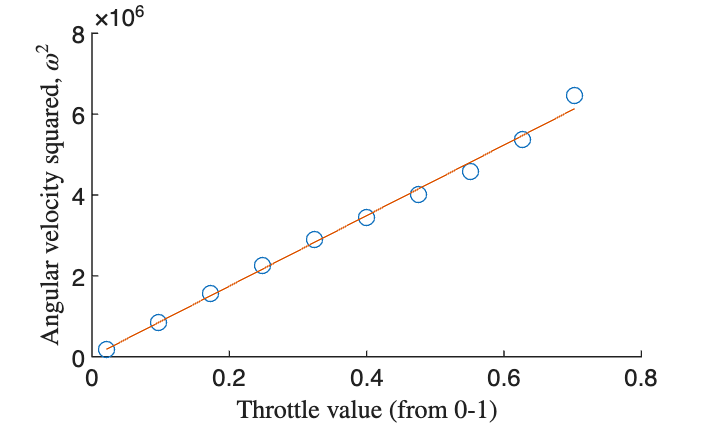


figure(1), clf, hold on
scatter(cmd, omega.^2)
plot(cmd, cmd2omegaSq(cmd))
xlabel("Throttle value (from 0-1)", Interpreter="Latex")
ylabel("Angular velocity squared, $\omega^2$", Interpreter="Latex")
hold off



omegaSq2thrust = fit(omega.^2, thrust, 'poly1');
k_t = omegaSq2thrust.p1

k_t = 1.3916e-06

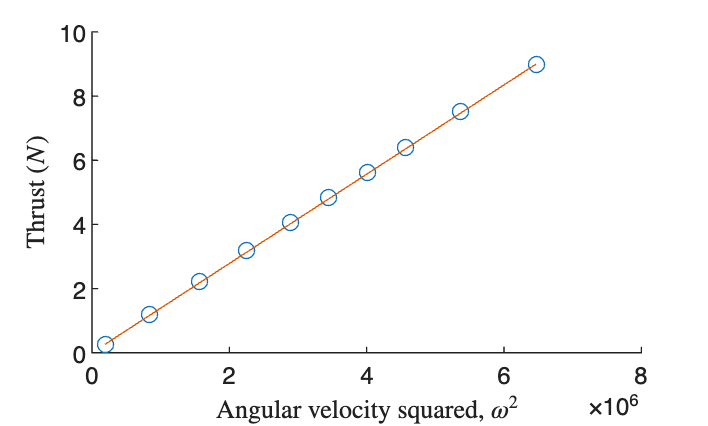


figure(2), clf, hold on
scatter(omega.^2, thrust)
plot(omega.^2, k_t*(omega.^2))
xlabel("Angular velocity squared, $\omega^2$", Interpreter="Latex")
ylabel("Thrust ($N$)", Interpreter="Latex")
hold off



omegaSq2drag = fit(omega.^2, drag, 'poly1');
k_q = omegaSq2drag.p1

k_q = 2.1628e-08

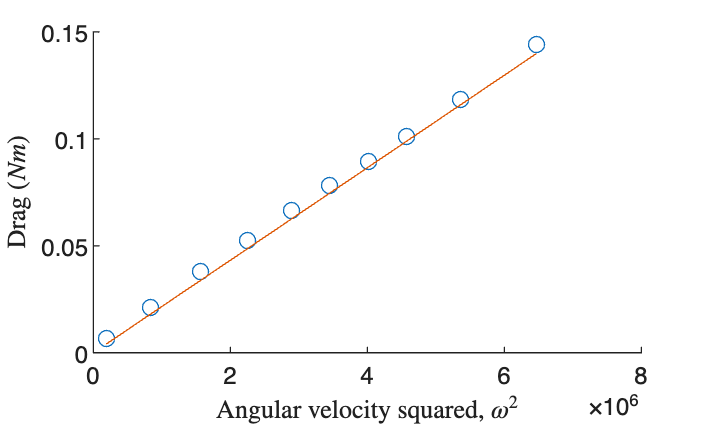


figure(3), clf, hold on
scatter(omega.^2, drag)
plot(omega.^2, k_q*(omega.^2))
xlabel("Angular velocity squared, $\omega^2$", Interpreter="Latex")
ylabel("Drag ($Nm$)", Interpreter="Latex")
hold off


f_max = k_t*(1*cmd2omegaSq_k)

f_max = 12.1400

load("Tyto_sample_1103_8000kv_2023x3_2S.mat")

cmd = (Throttles(2:end)-1228)/1000;
thrust = Thrustkgf(2:end)*9.807;
omega = RotationSpeedrpm(2:end)*(2*pi/60);
drag = TorqueNm(2:end);

cmd2omegaSq = fit(cmd, omega.^2, 'poly1');
cmd2omegaSq_k = cmd2omegaSq.p1

cmd2omegaSq_k = 2.0550e+07

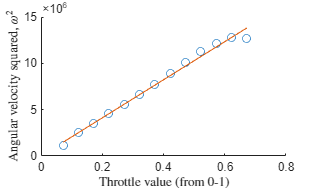


figure(1), clf, hold on
scatter(cmd, omega.^2)
plot(cmd, cmd2omegaSq(cmd))
xlabel("Throttle value (from 0-1)", Interpreter="Latex")
ylabel("Angular velocity squared, $\omega^2$", Interpreter="Latex")
hold off



omegaSq2thrust = fit(omega.^2, thrust, 'poly1');
k_t = omegaSq2thrust.p1

k_t = 3.7367e-08

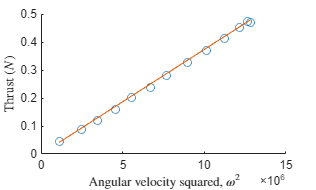


figure(2), clf, hold on
scatter(omega.^2, thrust)
plot(omega.^2, k_t*(omega.^2))
xlabel("Angular velocity squared, $\omega^2$", Interpreter="Latex")
ylabel("Thrust ($N$)", Interpreter="Latex")
hold off



omegaSq2drag = fit(omega.^2, drag, 'poly1');
k_q = omegaSq2drag.p1

k_q = 4.5029e-10

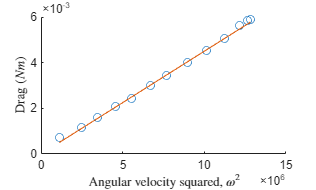


figure(3), clf, hold on
scatter(omega.^2, drag)
plot(omega.^2, k_q*(omega.^2))
xlabel("Angular velocity squared, $\omega^2$", Interpreter="Latex")
ylabel("Drag ($Nm$)", Interpreter="Latex")
hold off


f_max = k_t*(1*cmd2omegaSq_k )

f_max = 0.7679